clc; clear;
u = symunit;
CP = py.importlib.import_module("CoolProp.CoolProp");


middel = "R134a";
p3 = 8.868e5;
p4 = 1.330e5;

plin = linspace(p3, p4);

h3 = 241463;
h4 = h3;

hlin = linspace(h3,h4);
Ts = zeros(1,length(hlin));
Ds = zeros(1,length(hlin));
Vs = zeros(1,length(hlin));
Qs = zeros(1,length(hlin));


for i = 1:length(hlin)
Ts(i) = CP.PropsSI("T","H",hlin(i),"P",plin(i), middel) - 273.15;
Ds(i) = CP.PropsSI("D","H",hlin(i),"P",plin(i), middel);
Vs(i) = CP.PropsSI("V","H",hlin(i),"P",plin(i), middel);
Qs(i) = CP.PropsSI("Q","H",hlin(i),"P",plin(i), middel);
    if Qs(i) == -1
        Qs(i) = 1;
    else
        continue
    end
end
Qs

Qs =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.0005    0.0034    0.0063    0.0092    0.0121    0.0150    0.0179    0.0208    0.0238    0.0267    0.0297    0.0327    0.0357    0.0387    0.0417    0.0447    0.0477    0.0508    0.0538    0.0569    0.0600    0.0631    0.0662    0.0693    0.0724    0.0756    0.0787    0.0819    0.0851    0.0883    0.0916    0.0948    0.0981    0.1014


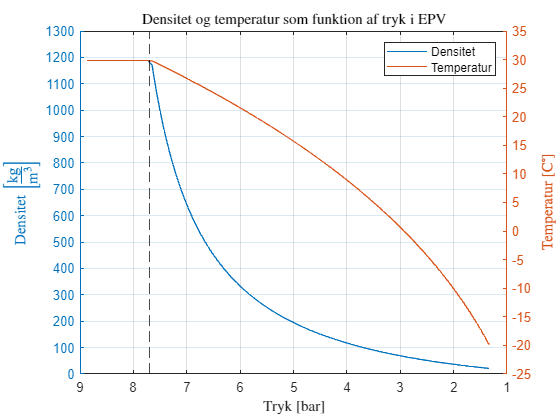

% Densitet temp
figure
title("Densitet og temperatur som funktion af tryk i EPV","Interpreter","latex")

grid("on")
yyaxis left
plot(plin/1e5, Ds)

ylim([0, 1300])
yticks(0:100:1300)


ylabel("Densitet $\left[\frac{\mathrm{kg}}{\mathrm{m^3}}\right]$","Interpreter","latex")

yyaxis right
plot(plin/1e5, Ts)

ylabel("Temperatur [C$^\circ$]","Interpreter","latex")

ylim([-25, 35])
yticks(-25:5:35)

xline(7.7, "k--")


set(gca, "XDir","reverse")

legend("Densitet","Temperatur","location","northeast")

xlabel("Tryk [bar]","Interpreter","latex")

exportgraphics(gcf, "DensTempTrykEPV.png")

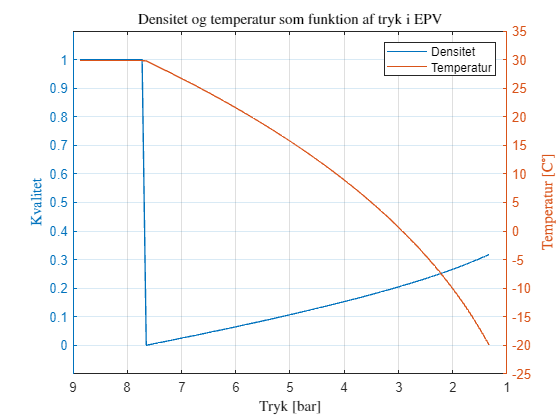

figure
title("Densitet og temperatur som funktion af tryk i EPV","Interpreter","latex")
grid("on")
yyaxis left
plot(plin/1e5, Qs)

ylim([-0.1, 1.1])
yticks(0:0.1:1)

ylabel("Kvalitet","Interpreter","latex")

yyaxis right
plot(plin/1e5, Ts)

ylabel("Temperatur [C$^\circ$]","Interpreter","latex")

ylim([-25, 35])
yticks(-25:5:35)

set(gca, "XDir","reverse")

legend("Densitet","Temperatur","location","northeast")

xlabel("Tryk [bar]","Interpreter","latex")

exportgraphics(gcf, "KvalTempTrykEPV.png")